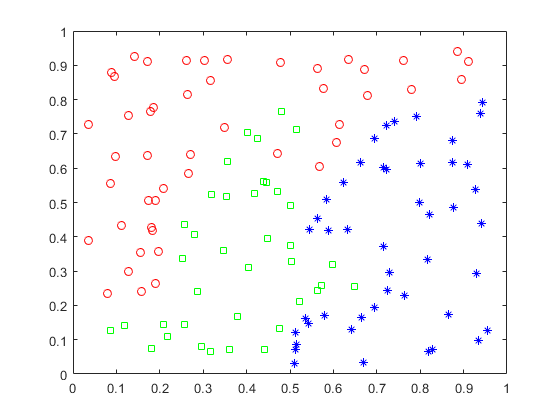

% Demo program na klasifikaciu predmetov skupiny A , B , C na základe vlastností V1 a V2 
% NS má 2 vstupy veliciny V1,V2 o rozsahu 0-1 (0-100%) a 3 výstupy o rozsahu 0-1, 
% kde hodnota 1.výstup prislúcha skupine A , 2. výstup skupine B a 3. výstup skupine C

echo on
% Príklad na klasifikáciu skupín A, B, C pomocou NS

% body sa zadaju naklikanim mysou a stlacenim klavesy enter
% data pre skupinu A

clear, clc, close all


h=figure;
title('Zadaj body skupiny A, naklikaj a stlac Enter')
axis([0 1 0 1])
[xA,yA]=ginput;
xA=xA'; yA=yA';     % suradnice bodov skupiny A

figure(h);
plot(xA,yA,'or')
hold on

% data pre skupinu B
figure(h);
axis([0 1 0 1])
title('Zadaj body skupiny B, naklikaj a stlac Enter')
[xB,yB]=ginput;
xB=xB'; yB=yB';     % suradnice bodov skupiny B

figure(h);
plot(xB,yB,'*b')

% data pre skupinu C
figure(h);
axis([0 1 0 1])
title('Zadaj body skupiny C, naklikaj a stlac Enter')
[xC,yC]=ginput;
xC=xC'; yC=yC';     % suradnice bodov skupiny C

figure(h);
plot(xC,yC,'sg')

figure
plot(xA,yA,'or')
hold on
plot(xB,yB,'*b')
plot(xC,yC,'sg')
axis([0 1 0 1])


% vstupné data pre NS
V1=[xA xB xC];
V2=[yA yB yC];
X=[V1;V2]

X =     0.6348    0.3560    0.1717    0.0887    0.0357    0.0357    0.0795    0.1578    0.1901    0.1970    0.1832    0.1740    0.2085    0.2661    0.2707    0.3491    0.4712    0.5680    0.6071    0.6141    0.6786    0.7800    0.8952    0.9113    0.8859    0.7615    0.6717    0.5772    0.5634    0.4781    0.3030    0.2615    0.1417    0.0956    0.1786    0.2638    0.3168    0.1279    0.0979    0.0864    0.1118    0.1279    0.1555    0.1809    0.1901    0.1717    0.1855    0.5104    0.5127    0.5127
    0.9169    0.9169    0.9111    0.8790    0.7274    0.3892    0.2347    0.2405    0.2638    0.3571    0.4184    0.5058    0.5408    0.5845    0.6399    0.7187    0.6429    0.6050    0.6749    0.7274    0.8120    0.8294    0.8586    0.9111    0.9402    0.9140    0.8878    0.8324    0.8907    0.9082    0.9140    0.9140    0.9257    0.8673    0.7653    0.8149    0.8557    0.7536    0.6341    0.5554    0.4329    0.2988    0.3542    0.4271    0.5058    0.6370    0.7770    0.0306    0.0714    0

% pocty bodov pre jednotlive skupiny
nA=length(xA);
nB=length(xB);
nC=length(xC);

% výstupne data pre NS, do ktorej skupiny bod patri, na ten vystup hodnota 1
P=[ones(1,nA) zeros(1,nB) zeros(1,nC);zeros(1,nA) ones(1,nB) zeros(1,nC);zeros(1,nA) zeros(1,nB) ones(1,nC)]

P =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



disp('---- stlac klavesu ----')

---- stlac klavesu ----


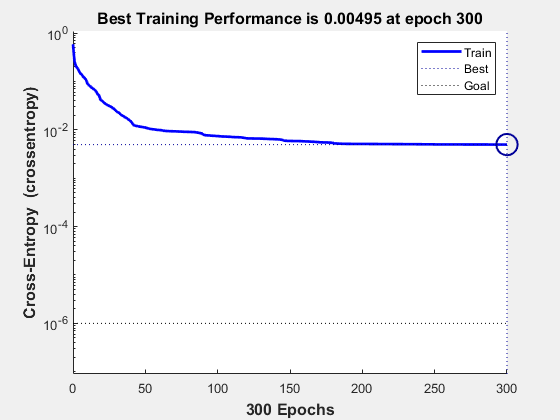

pause

% vytvorenie struktury NS na klasifikaciu
% vstupy a vystupy sa nastavia podla rozmerov vstupnych a vystupnych dat
% pocet skrytych neuronov je 10, aktivacna funkcia - tansig
% vystupna aktivacna funkcia - softmax, kriterialna funkcia cross-entropy 
net = patternnet(10);

% vsetky data pouzite na trenovanie
net.divideFcn='dividetrain';
% net.divideParam.trainRatio=1;
% net.divideParam.valRatio=0;
% net.divideParam.testRatio=0;

net.trainParam.goal = 0.000001;	    % Ukoncovacia podmienka na chybu SSE.
net.trainParam.epochs = 300;  	    % Max. pocet trénovacích cyklov.
net.trainParam.min_grad=1e-10;      % Ukoncovacia podmienka na min. gradient

% trenovanie siete
[net,tr] = train(net,X,P);


% zobrazenie chyby siete pocas trenovania
figure
plotperform(tr)


% simulacia vystupu NS
y = net(X);

% vypocet chyby siete
perf = perform(net,P,y)

perf = 0.0049


% priradenie vstupov do tried
classes = vec2ind(y)

classes =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     3     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2



disp('---- stlac klavesu ----')

---- stlac klavesu ----


pause


% testovacie data - naklikanie bodov mysou na testovanie siete
% %X2=rand(2,20);
figure(h);
axis([0 1 0 1])
title('Zadaj testovacie body ')
[xT,yT]=ginput;
X2=[xT';yT'];

% simulacia vystupu NS
y2 = net(X2)

y2 =     0.0000    0.0000    1.0000    1.0000    1.0000    1.0000    0.0000    1.0000    0.1083    1.0000    1.0000    1.0000    0.0000    0.0000    0.0000    0.9275    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.3372    1.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    0.0725    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    1.0000    0.0000   

retcolor='rbg';
% priradenie vstupov do tried
classes2 = vec2ind(y2)

classes2 =      3     3     1     1     1     1     3     1     3     1     1     1     3     2     2     1     1     2     2     2     2     2     2     2     2     2     2     2     3     3     3     3     3     1     1     1     1     1     1     1     3     1     1     3     3     3     3     3


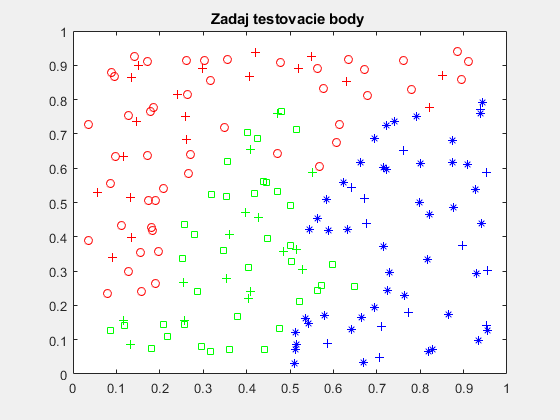

echo off
figure(h);
for k=1:size(X2,2)
   plot(X2(1,k),X2(2,k),[retcolor(classes2(k)) '+'])  
end

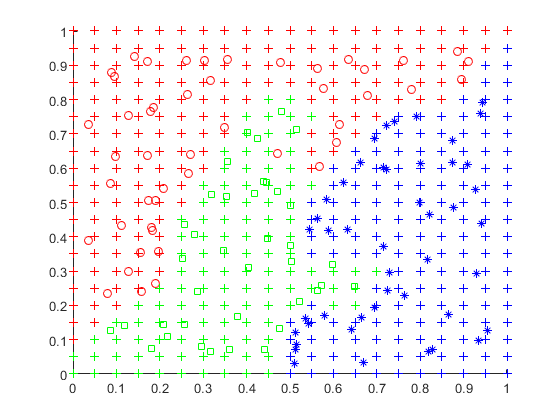


% vytvorenie rovnomernej testovacej siete bodov
[xTpom,yTpom]=meshgrid(0:0.05:1,0:0.05:1);
xT2=xTpom(1:end);
yT2=yTpom(1:end);
X3=[xT2; yT2];

% simulacia vystupu NS
y3=sim(net,X3);

classes3 = vec2ind(y3);

figure
hold on
plot(xA,yA,'or')
plot(xB,yB,'*b')
plot(xC,yC,'sg')
for k=1:size(X3,2)
   plot(X3(1,k),X3(2,k),[retcolor(classes3(k)) '+'])  
end